a=1+mod(964,3);

Q1

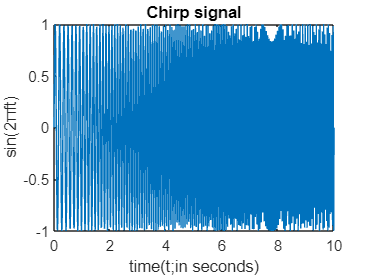

fs=100;
t=0:1/100:10;
f=linspace((2+2*a),(5+5*a),length(t));
x=sin(2*pi*f.*t);
audiowrite("chirp.wav",x,fs)

plot(t,x)
title('Chirp signal')
xlabel('time(t;in seconds)')
ylabel('sin(2πft)')

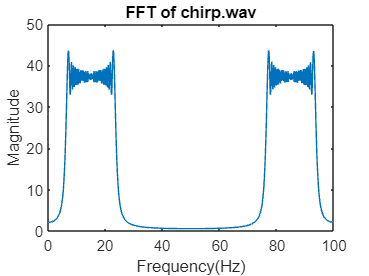


y=fft(x);
m=abs(y);
y(m<1e-5)=0;
fvec=(0:length(y)-1)*fs/length(y);
plot(fvec,m)
title('FFT of chirp.wav')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

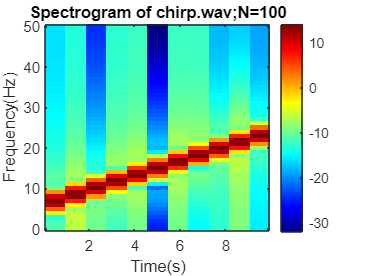


overlap=10;
N=100;
[S,F,t]=spectrogram(x,hamming(N),overlap,N,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav;N=100")

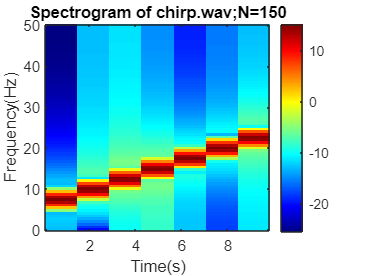


N=150;
[S,F,t]=spectrogram(x,hamming(N),overlap,N,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav;N=150")

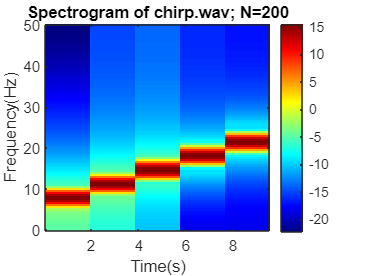


N=200;
[S,F,t]=spectrogram(x,hamming(N),overlap,N,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav; N=200")

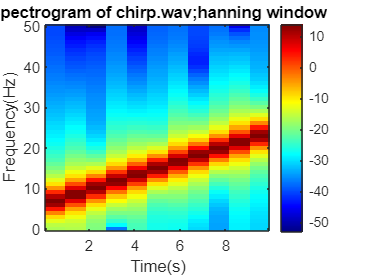


N=100;
[S,F,t]=spectrogram(x,hanning(N),overlap,N,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav;hanning window")

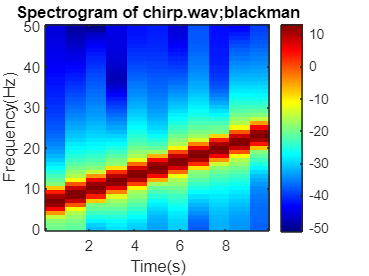


N=100;
[S,F,t]=spectrogram(x,blackman(N),10,N,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav;blackman")

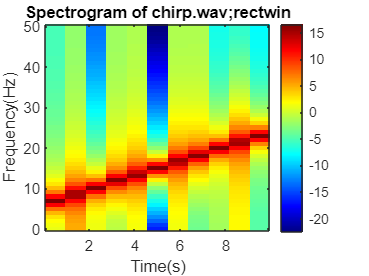


N=100;
[S,F,t]=spectrogram(x,rectwin(N),10,100,fs,"xaxis");
imagesc(t,F,10*log10(abs(S)));
axis xy;
colorbar
colormap('jet');
xlabel("Time(s)")
ylabel("Frequency(Hz)")
title("Spectrogram of chirp.wav;rectwin")

Q2

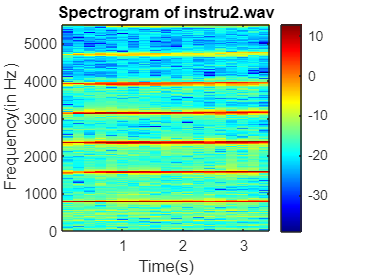

[s1,fs1]=audioread("instru2.wav");
[s2,fs2]=audioread("Opera.wav");

overlap=900;
N=2000;
[S1,F1,T1]=spectrogram(s1,hamming(N),10,1000,fs1,"xaxis");
imagesc(T1,F1,10*log10(abs(S1)));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of instru2.wav')


y1=fft(s1);
m1=abs(y1);
y1(m1<1e-5)=0;
fvec1=(0:length(y1)-1)*fs1/length(y1);
[~,idx1]=max(m1);
fun_freq1=fvec1(idx1)

fun_freq1 = 2.3691e+03

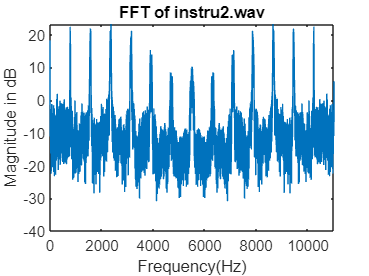

plot(fvec1,10*log10(m1))
title('FFT of instru2.wav')
xlabel('Frequency(Hz)')
ylabel('Magnitude in dB')

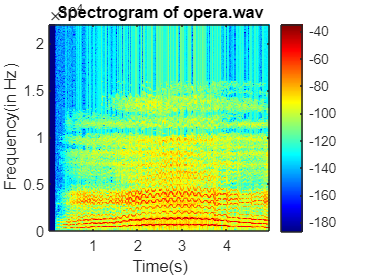



[~,F2,T2,PS2]=spectrogram(s2,hamming(N),900,1000,fs2,"xaxis");
imagesc(T2,F2,10*log10(PS2));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of opera.wav')


y2=fft(s2);
m2=abs(y2);
y2(m2<1e-5)=0;
fvec2=(0:length(y2)-1)*fs2/length(y2);
[~,idx2]=max(m2);
fun_freq2=fvec2(idx2)

fun_freq2 = 622.8000

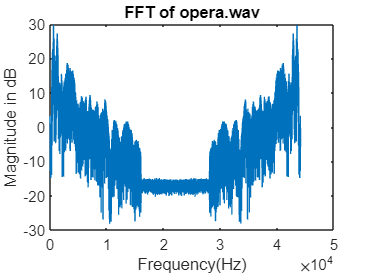

plot(fvec2,10*log10(m2))
title('FFT of opera.wav')
xlabel('Frequency(Hz)')
ylabel('Magnitude in dB')

Q3

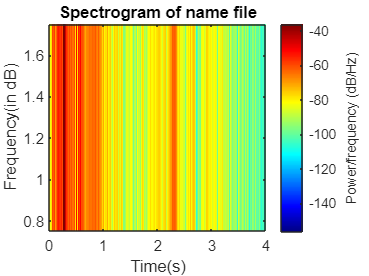

[n,fsn]=audioread("name.wav");
overlap=100;

spectrogram(n,hamming(N),900,1000,fsn,"xaxis");
xlabel('Time(s)')
ylabel('Frequency(in dB)')
title('Spectrogram of name file')